# Example Model: Counting Steps, Creating Graphics, Classifying Activity

*Copyright 2022 - 2025 The MathWorks, Inc*

To create a fitness tracker, you will first need to [collect sensor data and save it to MATLAB Drive](https://www.mathworks.com/help/matlabmobile/ug/sensor-data-collection-with-matlab-mobile.html). Once we have data, we can develop a model to take this data and output the information that we want. This section will take you through an example of making a model to convert GPS data to steps taken. Remember that **this is an example** and should only be used to help guide you to making your own model. While this is how we calculate steps taken, there are many other ways to do the same thing and we encourage that you try other ways to solve this same problem.

## Counting Steps

### 1. Preparing Data

To work with the data, we must first load it into the workspace and store the variables that are going to be used in this example. While we can double click on the data to load it, we will use the [`load`](https://www.mathworks.com/help/matlab/ref/load.html) command to make this process easier to replicate.

clear
load('ExampleData.mat');
lat=Position.latitude;
lon=Position.longitude;
positionDatetime=Position.Timestamp;

Xacc = Acceleration.X;
Yacc = Acceleration.Y;
Zacc = Acceleration.Z;
accelDatetime=Acceleration.Timestamp;

% We use the following to obtain linear time data in seconds from a datetime array
positionTime=timeElapsed(positionDatetime);
accelTime=timeElapsed(accelDatetime);

### 2. Determining Approach Method

Let’s say that you wanted to track the number of steps taken. One way that this can be done is by calculating the total distance traveled and then dividing it by your stride length. This works because stride is the distance taken for one step so if we look at the units they cancel out as seen below.

     
$$\frac{\textrm{totalDistance}\left(\textrm{ft}\right)}{\textrm{stride}\left(\frac{\textrm{ft}}{\textrm{step}}\right)}=\frac{\textrm{ft}}{\frac{\textrm{ft}}{\textrm{step}}}=\textrm{ft}*\frac{\textrm{step}}{\textrm{ft}}=\textrm{steps}$$


Now that we have an equation, the next step is to solve it in MATLAB. First, we need to get the total distance traveled, which is done using data from your GPS location or the latitude and longitude sensor data. One way that we can calculate this is by looking at your start location and end location and calculating the distance between those points. If we did that with the figure below, the distance traveled would be 300ft because the start and end position is 3 squares apart. 

 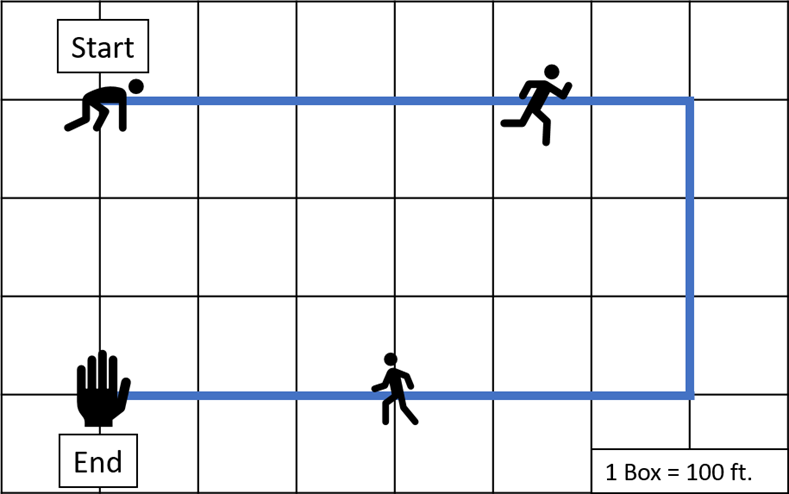

We can see that the person traveled much further than this, so we must calculate the distance along the path using **each data point**. Now we can accurately calculate that the person traveled 1500ft, which is a large difference from the 300ft originally calculated. 

Once we have an accurate measure of distance, we can divide this by average stride length to calculate number of steps taken!

### 3. Coding The Model

In this example, latitude and longitude have been stored into variable names *lat* and *lon* respectively. The first step in using these to calculate distance is to declare a couple of variables: one will represent the circumference of the earth in miles, the other will represent the total distance traveled, which will be set to zero for now.

earthCirc = 24901;
totaldis = 0;

To solve this problem, calculations will have to be repeated several times in a loop. Because of this, we use a function called a [`for loop`](https://www.mathworks.com/help/matlab/ref/for.html) which will repeat a block of code *for* a specified number of times. In this case, we want to have it run until the end of our vector of data. The [`length`](https://www.mathworks.com/help/matlab/ref/double.length.html) command can be used to determine the number of elements in a vector and therefore how many times we need to run the loop. When solving for the difference in position, one position and the next position are used at the same time, so we need to stop one before the end of the vector as seen below. If this isn't done, we will get an error because we will be trying to acces data from outside of the vector.

for i = 1:(length(lat)-1)

Now we save the first position and the second position into variables. We will do this using the variable *i* from above. This variable is a vector from 1 to the end of our latitude vector which can be used to index the latitude and longitude vectors.

    lat1 = lat(i);     % The first latitude
    lat2 = lat(i+1);   % The second latitude
    lon1 = lon(i);     % The first longitude
    lon2 = lon(i+1);   % The second longitude

Thankfully for us, MATLAB has a command [`distance`](https://www.mathworks.com/help/map/ref/distance.html) that calculates distance when given latitude and longitude. This will give us the difference in degrees which we will then turn into length by creating equivalent fractions:


$$\frac{\textrm{traveledDistance}}{\textrm{earth'sCircumference}}=\frac{\textrm{degreesTraveled}}{\textrm{earth'sDegrees}}\;$$


From this we solve for 'traveledDistance'. We will use 360 for 'earth’sDegrees' because that is the total number of degrees in a circle. While the earth is not a perfect circle, this will still be a good estimation

    degDis = distance(lat1, lon1, lat2, lon2);
    dis = (degDis/360)*earthCirc;

Now we add up the distance and store it into the *totaldis* variable. What this code will do is take the previous total distance and add the distance just calculated onto it. With this, we have calculated everything that we needed to within the for loop and must close the loop by using the [`end`](https://www.mathworks.com/help/matlab/ref/end.html) command.

    totaldis = totaldis + dis;
end

Once the for loop has finished, we will have the total distance traveled! From here, we need to divide the total distance traveled by the stride to get the steps taken. For this example, we will use the average stride of 2.5ft. Since *totaldis* is the total distance traveled in miles, we will have to convert this into feet before we can divide it by the stride. 

stride = 2.5;                   % Average stride (ft)
totaldis_ft = totaldis*5280;    % Converting distance from miles to feet
steps = totaldis_ft/stride;

An easy way to see the data that you are interested in is by priniting it to the screen once you find it. While you could also show it by removing the semicolon, the [`disp`](https://www.mathworks.com/help/matlab/ref/disp.html) command allows you to add text as well to specify exactly what data you are looking at.

disp(['The total distance traveled is: ', num2str(totaldis),' miles'])

The total distance traveled is: 0.4093 miles


disp(['You took ', num2str(steps) ' steps'])

You took 864.4514 steps


## Classifying Activity

In addition to counting steps, let's say that you want to know what kind of activity you were doing. Let's train a machine learning model that takes a person's acceleration data and shows if they were sitting, walking, or running.

### 1. Prepare the data

First, you'll need to collect sensor data for each of these activities. For simplicity, I collected this data in three different sessions: one where I was sitting the whole time ('sitAcceleration'), one where I was walking ('walkAcceleration'), and one where I was running ('runAcceleration'). This is just a sample dataset, and you may wish to collect more data when training your own model for higher accuracy. 

Let's load the logs for these sessions and preview one of them to get a sense of how the data is structured.

load ActivityLogs 
head(sitAcceleration) 

           Timestamp               X         Y         Z   
    ________________________    _______    ______    ______

    20-Jul-2023 13:34:44.644      2.138    3.1268    10.077
    20-Jul-2023 13:34:44.724     1.1684    2.8754    8.8657
    20-Jul-2023 13:34:44.804    0.93134     3.146     9.335
    20-Jul-2023 13:34:44.884    0.69192    3.2729     8.746
    20-Jul-2023 13:34:44.964     1.1851    3.3974    9.1722
    20-Jul-2023 13:34:45.044     1.1803    3.4093    9.1626
    20-Jul-2023 13:34:45.124     1.0654    3.3423    8.6335
    20-Jul-2023 13:34:45.204     1.5778    3.5147    9.7779



Now we need to add the activity labels to each table.

sitLabel = 'sitting';
sitLabel = repmat(sitLabel, size(sitAcceleration, 1), 1);
sitAcceleration.Activity = sitLabel

sitAcceleration = 390×4 timetable
           Timestamp                X          Y         Z       Activity
    ________________________    _________    ______    ______    ________

    20-Jul-2023 13:34:44.644        2.138    3.1268    10.077    sitting 
    20-Jul-2023 13:34:44.724       1.1684    2.8754    8.8657    sitting 
    20-Jul-2023 13:34:44.804      0.93134     3.146     9.335    sitting 
    20-Jul-2023 13:34:44.884      0.69192    3.2729     8.746    sitting 
    20-Jul-2023 13:34:44.964       1.1851    3.3974    9.1722    sitting 
    20-Jul-2023 13:34:45.044       1.1803    3.4093    9.1626    sitting 
    20-Jul-2023 13:34:45.124       1.0654    3.3423    8.6335    sitting 
    

% Repeat for walking data
walkLabel = 'walking';
walkLabel = repmat(walkLabel, size(walkAcceleration, 1), 1);
walkAcceleration.Activity = walkLabel;

% Repeat for running data
runLabel = 'running';
runLabel = repmat(runLabel, size(runAcceleration, 1), 1);
runAcceleration.Activity = runLabel;

Then we should combine all of our data into one table.

allAcceleration = [sitAcceleration; walkAcceleration; runAcceleration];

Last, we can remove the 'Timestamp' variable, since this variable does not help determine what type of activity we are doing.

allAcceleration = timetable2table(allAcceleration, "ConvertRowTimes", false)

allAcceleration = 1121×4 table
        X          Y         Z       Activity
    _________    ______    ______    ________

        2.138    3.1268    10.077    sitting 
       1.1684    2.8754    8.8657    sitting 
      0.93134     3.146     9.335    sitting 
      0.69192    3.2729     8.746    sitting 
       1.1851    3.3974    9.1722    sitting 
       1.1803    3.4093    9.1626    sitting 
       1.0654    3.3423    8.6335    sitting 
       1.5778    3.5147    9.7779    sitting 
      0.76375    3.2801       8.6    sitting 
      0.98881    3.2537    9.2344    sitting 
       1.7238    4.1276    8.8992    sitting 
    -0.019154    2.9592     9.007    sitting 
      0.87149    2.6456     9.098    sitting 
       1.0343    3.0311    9.3781    sitting 
       1.1971    3.3686    9.2129    sitting 
      0.93134    3.4476     8.928    sitting 


Now the data is ready to be used for training!

### 2. Train a model

One way to train several different machine learning algorithms at once is to use the Classification Learner App, which allows you to rapidly prototype and fine tune your models until you have one you are happy with. You have a lot of options on how to use your data and train models in this app, so while this will be a basic workflow, you can learn more about the different options using this [documentation](https://www.mathworks.com/help/stats/classification-learner-app.html). 

First, open the app:

classificationLearner

Start a "New Session" and select "From Workspace". In the window that opens, select `allAcceleration` as the 'Data Set Variable', then start the session. 

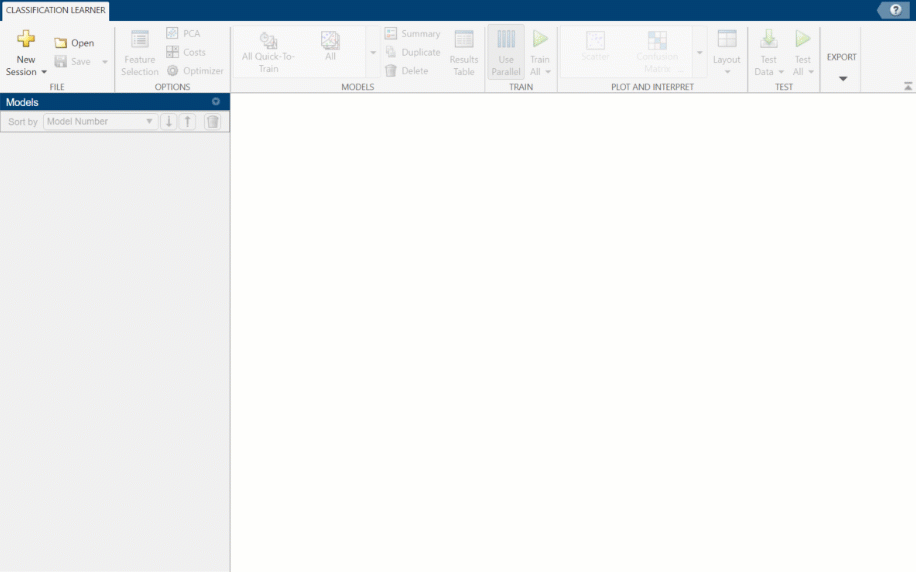

From the 'Models' section of the toolstrip, select 'All Quick-To-Train'. This will add a model labeled 'Multiple' to the 'Models' tab. Then delete the model labeled 'Tree'.

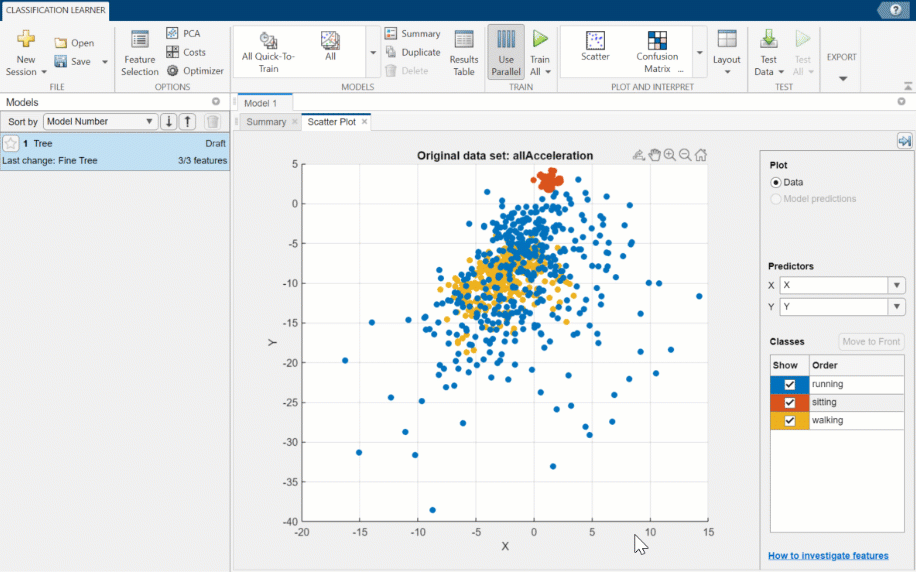

Click 'Train All', which will start training several models. Once the training has finished, each model will have an 'RMSE (Validation)' value. This represents the *root mean squared error* of that model when used on a subset of the training data. The lower the RMSE, the better the model performed. Select the model with the lowest RMSE, then export the model to the workplace.

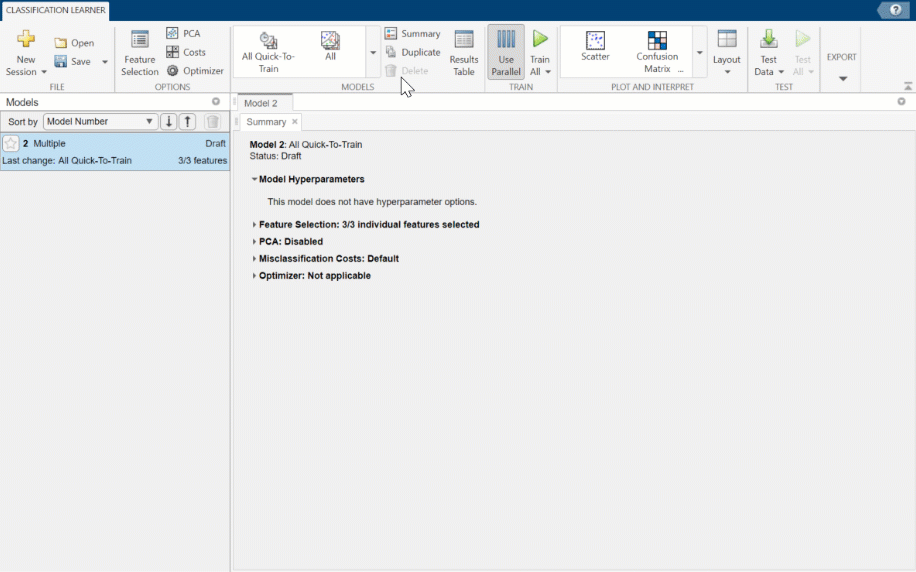

### 3. Use the model

Now we can use that model to make predictions on new data! 'unknownAcceleration' (from ActivityLogs.mat, which we loaded earlier) is a log of acceleration data collected during a sample workout that included walking, running, and sitting, so we can use our machine learning model to predict what activity the person was doing for each timestamp. 

unknownAcceleration % preview data to ensure the correct format

unknownAcceleration = 2174×3 timetable
           Timestamp                X           Y           Z    
    ________________________    _________    _______    _________

    26-Jul-2023 13:27:54.764      -3.1795    -9.1123       1.1516
    26-Jul-2023 13:27:54.844      -3.0287    -9.2703       1.3144
    26-Jul-2023 13:27:54.924      -3.2178    -9.0285       1.2546
    26-Jul-2023 13:27:55.004      -3.1603    -9.1243       1.2761
    26-Jul-2023 13:27:55.084      -3.0574    -9.1051       1.1947
    26-Jul-2023 13:27:55.164      -2.9999    -8.8897       1.4581
    26-Jul-2023 13:27:55.244      -2.1596    -8.2696    -0.011971
    26-Jul-2023 13:27:55.324      -1.6496    -9.1842      -1.8483
    26-Jul-2023 13:2

justAcc = timetable2table(unknownAcceleration, "ConvertRowTimes", false);
yfit = trainedModel.predictFcn(justAcc)

yfit = 2174×7 char array
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'running'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walk

## Creating Graphics

There are many ways in which you can visualize data in MATLAB. Say we wanted to graph the acceleration data that we took earlier to compare how the X, Y and Z data compare against one another. We can do this using the [`plot`](https://www.mathworks.com/help/matlab/ref/plot.html) command. The only problem with this command is plotting multiple data on the same graph the code can be messy in one line. Because of this, we use the [`hold on`](https://www.mathworks.com/help/matlab/ref/hold.html) command to plot multiple lines on the same graph. Don't forgot to also use` hold off `when you are done or else everything you plot will go on the same graph.

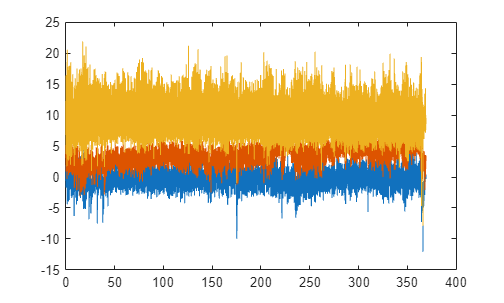

plot(accelTime,Xacc);
hold on;
plot(accelTime,Yacc); 
plot(accelTime,Zacc);
hold off

In the graph we just made it is very difficult to differentiate between the lines because there is so much data being graphed in such a small window. We will want to zoom in on the graph in order to see any trends between the different data lines. To do this, we set a limit on the x axis usng [`xlim`](https://www.mathworks.com/help/matlab/ref/xlim.html) so that we can look at the first 50 seconds of data.

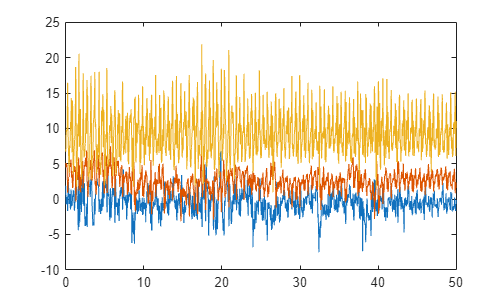

plot(accelTime,Xacc);
hold on;
plot(accelTime,Yacc); 
plot(accelTime,Zacc);
xlim([0 50])
hold off

While this isn't the prettiest graph, it still gives a better idea as to what each data line looks like. Now we need to add labels onto the graph so that we may know which line corresponds to which set of data. We will also want to add a title and labels onto this graph so that someone who doesn't know what this data is can read the graph without looking at the code.

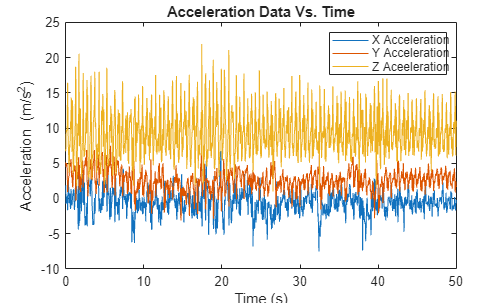

plot(accelTime,Xacc);
hold on;
plot(accelTime,Yacc); 
plot(accelTime,Zacc);
xlim([0 50])
legend('X Acceleration','Y Acceleration','Z Aceeleration');
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)');
title('Acceleration Data Vs. Time');
hold off

With this, we now have a meaningful graph! There are many other properties that we can add and edit on this graph depending on the kind of information we want to display. One important tool when it comes to graphing is called the [`LineSpec`](https://www.mathworks.com/help/matlab/ref/plot.html#btzitot_sep_mw_3a76f056-2882-44d7-8e73-c695c0c54ca8) or line specification, which allows us to edit the properties of the graph. To learn about the many customization options available when plotting, check out the [`plot `documentation page](https://www.mathworks.com/help/matlab/ref/plot.html)!

There may also be times where you want to visualize the results of the machine learning model to show a summary of the person's workout. If we want a summary of the activities completed during a workout, we can create a [pie chart](https://www.mathworks.com/help/matlab/ref/pie.html):

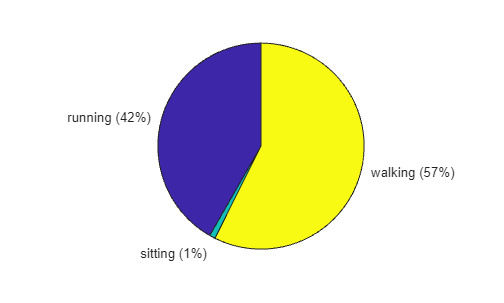

yfitcat = categorical(cellstr(yfit)); % convert to correct data type for histogram
pie(yfitcat)

Check out this [documentation page](https://www.mathworks.com/help/matlab/2-and-3d-plots.html) to learn more about other plotting options available!

## Your Turn!

Now that you've seen a few ways to work with sensor data, get creative with it! What kinds of information would you want to see in a fitness tracker? There are other sensors available in MATLAB Mobile, take a look at the full list ([available here](https://www.mathworks.com/help/matlabmobile/ug/sensor-data-collection-with-matlab-mobile.html#mw_00201d65-d61e-4f53-afec-69684d34e5c6)) and think about what kind of measurements you can derive. For things that may be too complicated to calculate using a single formula, can you utilize AI models? How can you test your machine learning models to ensure they are high quality before putting them in your final product?

If you're looking for inspiration or just want to learn more, take a look at the resources below to learn more about using and visualizing sensor data!

- [Classifying Activities using Signal Data and Machine Learning](https://www.mathworks.com/help/signal/ug/human-activity-recognition-using-signal-feature-extraction-and-machine-learning.html)

- [Sensor Data Collection Documentation](https://www.mathworks.com/help/matlabmobile/sensor-data-collection.html?s_tid=CRUX_lftnav) (with examples)

- [MATLAB Mobile Documentation](https://www.mathworks.com/help/matlabmobile/index.html)

- [Types of MATLAB Plots](https://www.mathworks.com/help/matlab/creating_plots/types-of-matlab-plots.html)

- [Check Model Performance Using Test Set in Regression Learner App](https://www.mathworks.com/help/stats/check-model-performance-using-test-set-in-regression-learner.html)